**Giordano Dylan - Martelet Curtis                            M1 EEA Grp C**

# Rapport TP4: Hacheur 4 Quadrants et MCC en Boucle Ouverte

## 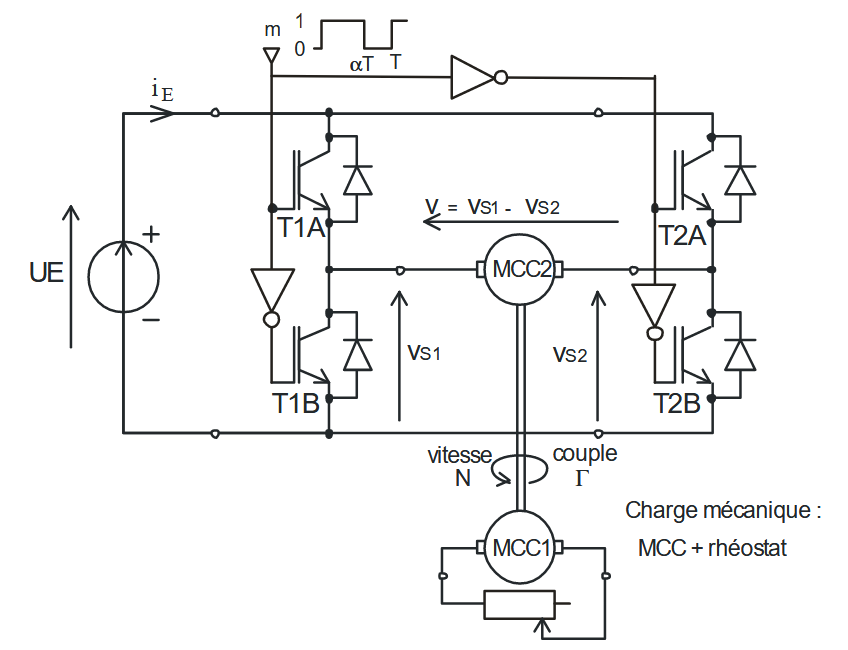

## 2) Essai préliminaires 

### 1. Caractérisation de la MCC2

- $U_N =60V;I_N =2A;N_N =3350\;\textrm{tr}/\textrm{mn}$.

- $k\phi =65\ldotp 6m$.

- $R=0\ldotp 552\Omega$.

## 3) Caractérisation d'un hacheur 4Q et d'une MCC en boucle ouverte

### 1. Fonctionnement à vide

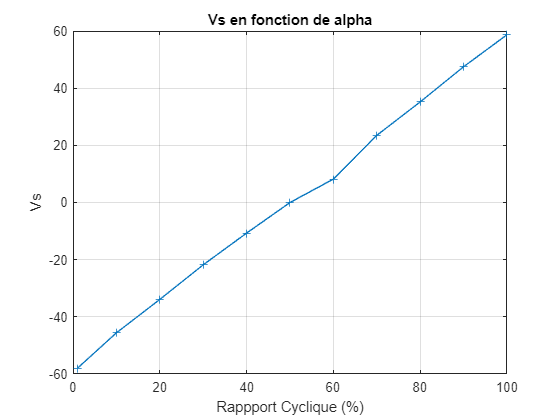

k = 65.6e-3;R=0.552;%a vérifier
Ue=60;
alpha=[0.01 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1]*100;
Vs=[-58 -45.6 -33.9 -21.8 -10.7 0 8.19 23.5 35.2 47.5 58.7];
N=[-3900 -3100 -2270 -1410 -650 0 685 1540 2313 3153 3930];

figure()
plot(alpha,Vs,'-+');
title('Vs en fonction de alpha')
xlabel('Rappport Cyclique (%)'); ylabel('Vs')
grid on

La variation de vitesse du moteur est presque linéaire pour un rapport cyclique entre 0 et 100%.

$V=R\times I+E$avec $E=k\times \Omega$. On considère le courant nul puisque l'on est en fonctionnement à vide donc : $\Omega =\frac{V}{k}$ avec $\Omega =\frac{N\times 2\pi }{60}$

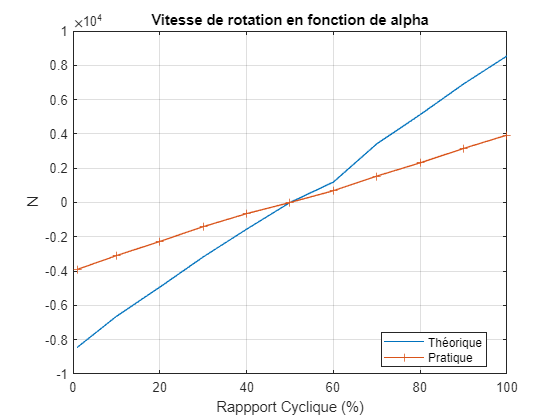

N_theo = (60/2/pi)*(Vs./k);
N=[-3900 -3100 -2270 -1410 -650 0 685 1540 2313 3153 3930];

figure()
plot(alpha,N_theo,alpha,N,'-+');
title('Vitesse de rotation en fonction de alpha')
xlabel('Rappport Cyclique (%)'); ylabel('N');legend("Théorique","Pratique",Location="best")
grid on

On peut observer que la courbe théorique et la courbe pratique ont la même allure.

Dans le cas où c'est la tension d'alimentation varie et le rapport cyclique qui reste fixe, alors la vitesse de rotation du moteur variera en fonction de Ve.

Pour rappel, la tension en sortie du hacheur varie en fonction et, du rapport cyclique, et, de la tension en entrée de ce dernier : $V_S =\left(2\alpha -1\right)\times V_E$.

### 2. Effet du couple résistant sur la vitesse de rotation

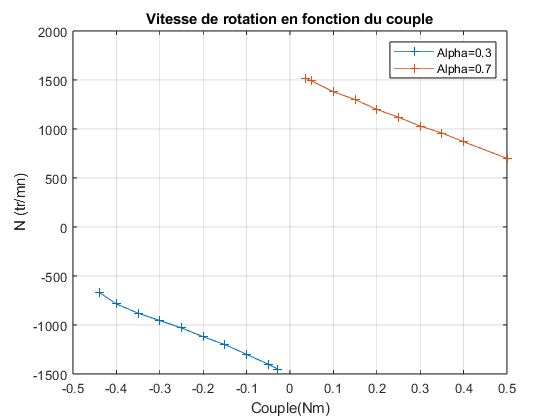

Couple_03 = [0.028 0.05 0.1 0.15 0.2 0.25 0.3 0.35 0.4 0.44].*-1; %négatif
Couple_07 = [0.036 0.05 0.1 0.15 0.2 0.25 0.3 0.35 0.4 0.5];

N_03=[1450 1400 1300 1200 1120 1030 955 880 785 666].*-1;
N_07=[1520 1490 1380 1300 1200 1120 1030 959 870 700];

figure()
plot(Couple_03,N_03,'-+',Couple_07,N_07,'-+')
title('Vitesse de rotation en fonction du couple')
xlabel('Couple(Nm)'); 
ylabel('N (tr/mn)')
legend("Alpha=0.3","Alpha=0.7")
grid on

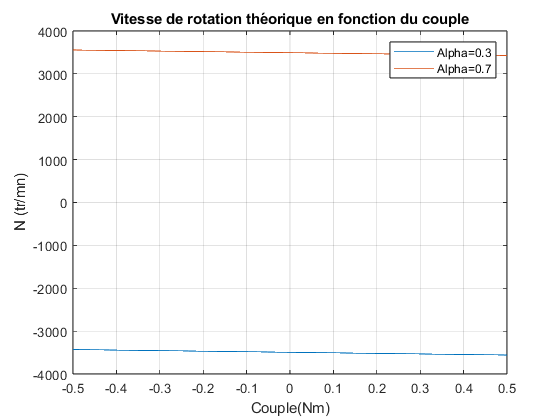

% PARTIE THEORIQUE
couple = linspace(-0.5,0.5,100);
alpha2 = 0.7; alpha1 = 0.3;
N1_theorique = (60/2/pi)*(60*(2*alpha1-1)/k)-((R.*couple)./k^2);
N2_theorique = (60/2/pi)*(60*(2*alpha2-1)/k)-((R.*couple)./k^2);

figure()
plot(couple,N1_theorique,couple,N2_theorique);
title('Vitesse de rotation théorique en fonction du couple')
xlabel('Couple(Nm)'); 
ylabel('N (tr/mn)')
legend("Alpha=0.3","Alpha=0.7")
grid on

## 4) Alimentation en vitesse variable d’un MCC avec un hacheur 2 quadrants

### 1. Hacheur 2 quadrant avec un courant de sortie positif

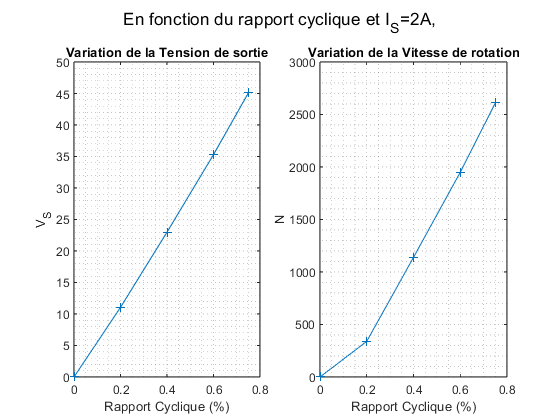

alpha_2Q=[0 0.2 0.4 0.6 0.75];
Ue = 60; Is=2;
Vs1=[0 11.06 23 35.3 45.1];
N_2Q=[0 340 1140 1950 2610];

figure()
sgtitle('En fonction du rapport cyclique et I_S=2A,')
subplot(1,2,1)
plot(alpha_2Q,Vs1,'-+')
title('Variation de la Tension de sortie')
xlabel('Rapport Cyclique (%)'); ylabel('V_S');grid("minor")
subplot(1,2,2)
plot(alpha_2Q,N_2Q,'-+')
title('Variation de la Vitesse de rotation')
xlabel('Rapport Cyclique (%)'); ylabel('N');grid("minor")

L'allure de la variation de la vitesse de rotation est identique (parallèle même) à celle de la tension de sortie.

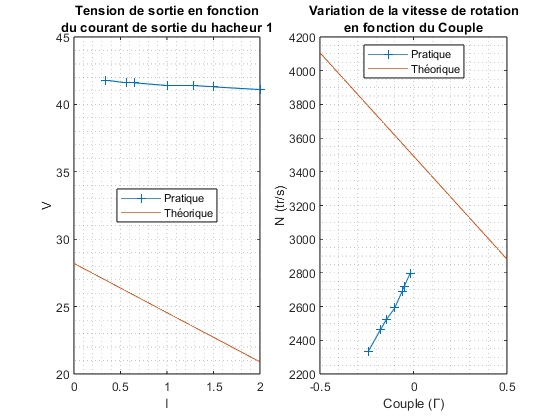

figure()
Is1=[0.34 0.56 0.65 1 1.29 1.5 2];
Vs1=[41.8 41.6 41.6 41.4 41.4 41.3 41.1];

Couple=[-0.018 -0.049 -0.061 -0.1 -0.146 -0.176 -0.242];
N=[2797 2722 2691 2592 2522 2464 2334];

V = 60*(2*0.7-1);

Couple_theorique = linspace(-0.5,0.5,100);
N_theorique = (60/2/pi)*((V/k)-((R.*Couple_theorique)./k^2));

Is1_theorique = linspace(0,2,100);
Vs1_theorique = (k.*N_theorique)*(2*pi/60)+R.*Is1_theorique;

subplot(1,2,1)
plot(Is1,Vs1,'-+',Is1_theorique,Vs1_theorique)
title(["Tension de sortie en fonction","du courant de sortie du hacheur 1"])
legend("Pratique","Théorique",Location="best")
xlabel('I'); ylabel('V');grid("minor")

subplot(1,2,2)
plot(Couple,N,'-+',Couple_theorique,N_theorique)
title(["Variation de la vitesse de rotation","en fonction du Couple"])
legend("Pratique","Théorique",Location="best")
xlabel('Couple (Γ)'); ylabel('N (tr/s)');grid("minor")

Les courbes théoriques et pratiques n'ont absolument pas la même allure.

Je pense que mes équations pour réaliser le comportement théorique est en cause, mais il n'est pas complètement impossible que nos relevés de valeurs soient erronés. 